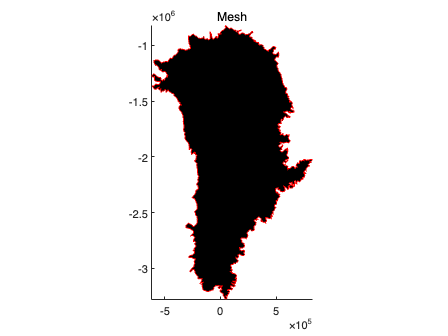

% Use the .exp file to make the triangular mesh
md = triangle(model,'/Users/rishi/Desktop/ISSM/examples/Helheim/GreenlandOutline.exp',2000);
plotmodel(md,'data','mesh')
hold on
expdisp('/Users/rishi/Desktop/ISSM/examples/Helheim/GreenlandOutline.exp')

## Interpolate observed surface velocities onto the current mesh

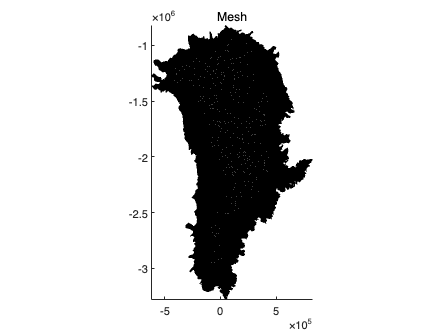

[velx, vely]=interpJoughinCompositeGreenland(md.mesh.x,md.mesh.y,...
    '/Users/rishi/Desktop/ISSM/examples/Data/');
vel = sqrt(velx.^2+vely.^2);

% Refine mesh based on surface velocitie s
md=bamg(md,'hmin',2000,'hmax',15000,'field',vel,'err',5);
[md.mesh.lat,md.mesh.long] = xy2ll(md.mesh.x,md.mesh.y,+1,45,70);
md.mesh.epsg=3413;

% plot the mesh to check the triangle adjustment
plotmodel(md,'data','mesh')

## Parameterization of the model

Step - 1 Interpolate the datasets from the Bedmachine-Greenland-v5

md=setflowequation(md,'SSA','all'); % Set flow law to SSA for original 2d mesh
md=setmask(md,'','');
md=parameterize(md,'/Users/rishi/Desktop/ISSM/examples/Jakobshavn/Greenland.par'); % can be used for any Greenland glacier

   Interpolating mask
   -- BedMachine Greenland version: v5
   -- BedMachine Greenland: loading mask
   -- BedMachine Greenland: interpolating mask
       -- Interpolation method: nearest
      reading MC bed (assumes no floating ice)
   -- BedMachine Greenland version: v5
   -- BedMachine Greenland: loading bed
   -- BedMachine Greenland: interpolating bed
       -- Interpolation method: cubic
      reading Howat surface
   -- BedMachine Greenland version: v5
   -- BedMachine Greenland: loading surface
   -- BedMachine Greenland: interpolating surface
       -- Interpolation method: cubic
   Adjusting ice mask
      -- reconstruct thickness
      reading velocities 
   Creating flow law parameters (assume ice is at 0°C for now)
   Geothermal flux from Shapiro et al.
   Setting up thermal model
   Set Boundary conditions


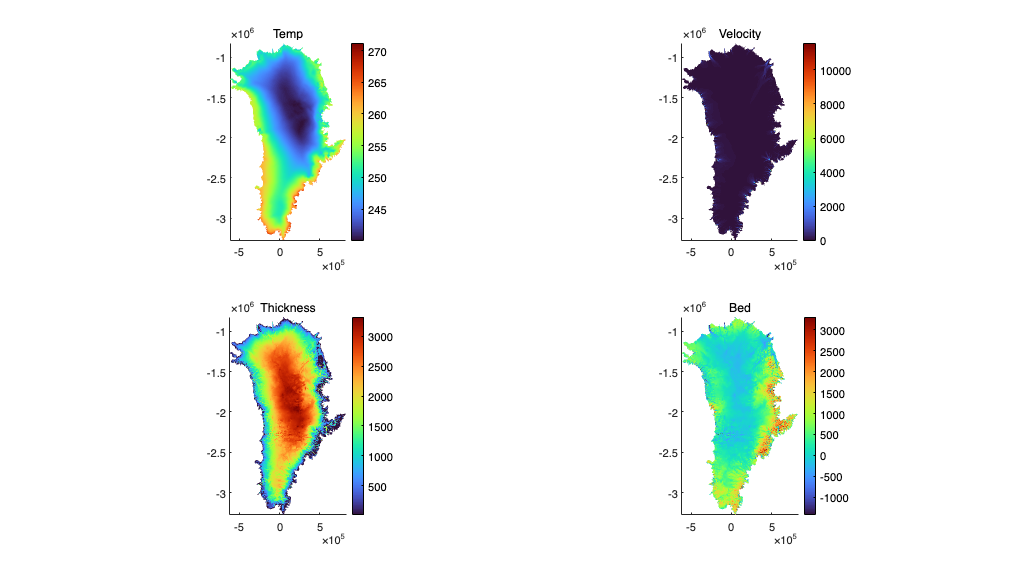

md.miscellaneous.name = 'Greenland_BedMachine';

% Plot the parameters interpolated from the input data
plotmodel(md,'data',...
    md.initialization.temperature,'title','Temp', ...
    'data', md.initialization.vel,'title','Velocity', ...
    'data',md.geometry.thickness,'title','Thickness', ...
    'data',md.geometry.bed,'title','Bed','figposition','fullscreen')

## Model parameters

%Control general
md.inversion=m1qn3inversion(md.inversion);
md.inversion.iscontrol=1;
md.verbose=verbose('solution',false,'control',true);
md.transient.amr_frequency = 0;

%Cost functions
md.inversion.cost_functions=[101 501];
md.inversion.cost_functions_coefficients=zeros(md.mesh.numberofvertices,2);
md.inversion.cost_functions_coefficients(:,1)=50;
md.inversion.cost_functions_coefficients(:,2)= 2e-9;
pos=find(md.mask.ocean_levelset<0 | md.mask.ice_levelset>0);
md.inversion.cost_functions_coefficients(pos,1:2)=0;
md.stressbalance.spcvx(pos)=md.initialization.vx(pos);
md.stressbalance.spcvy(pos)=md.initialization.vy(pos);

%Controls
md.inversion.control_parameters={'FrictionCoefficient'}; % parameters to invert
md.inversion.maxsteps=100; % maximum steps of inversion
md.inversion.maxiter =100; % maximum iterations
md.inversion.min_parameters=0.05*ones(md.mesh.numberofvertices,1);
md.inversion.max_parameters=300*ones(md.mesh.numberofvertices,1);
md.inversion.control_scaling_factors=1;

%Additional parameters
md.stressbalance.restol= 0.01;
md.stressbalance.reltol= 0.1;
md.stressbalance.abstol= NaN;
md.initialization.pressure=zeros(md.mesh.numberofvertices,1);

%Go solve
md.cluster=generic('name',oshostname,'np',4);
md=solve(md,'sb');

## Plot the velocity and Friction Coefficient

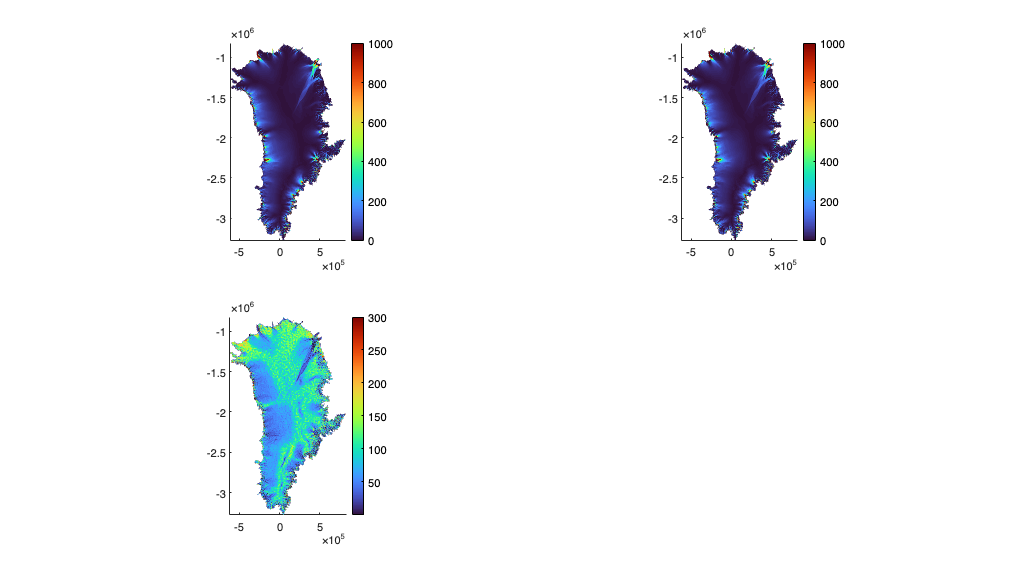

plotmodel(md,...
'data', md.initialization.vel,'caxis#1',[0 1000],...
'data',md.inversion.vel_obs,'caxis#2',[0 1000],...
'data',md.results.StressbalanceSolution.FrictionCoefficient)

## Calculate Mechanical properties of ice - Stress and Strain

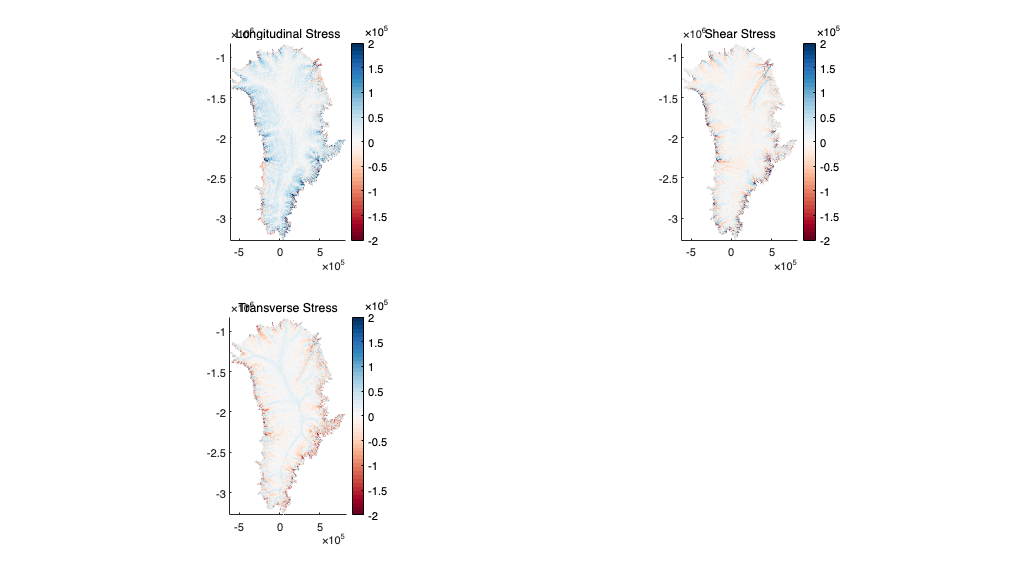

md = mechanicalproperties(md, md.results.StressbalanceSolution.Vx, ...
    md.results.StressbalanceSolution.Vy);

% Flow oriented Stress and Strain rates
md = flow_oriented_stress_strain(md, md.results.StressbalanceSolution.Vx, ...
    md.results.StressbalanceSolution.Vy);

plotmodel(md,'data',md.results.deviatoricstress.longitudinal,'caxis#1',[-2e5 2e5],'title','Longitudinal Stress', ...
    'data',md.results.deviatoricstress.shear,'caxis#2',[-2e5 2e5],'title','Shear Stress', ...
    'data',md.results.deviatoricstress.transverse,'caxis#3',[-2e5 2e5],'title','Transverse Stress')

colormap(brewermap(50,'RdBu'))